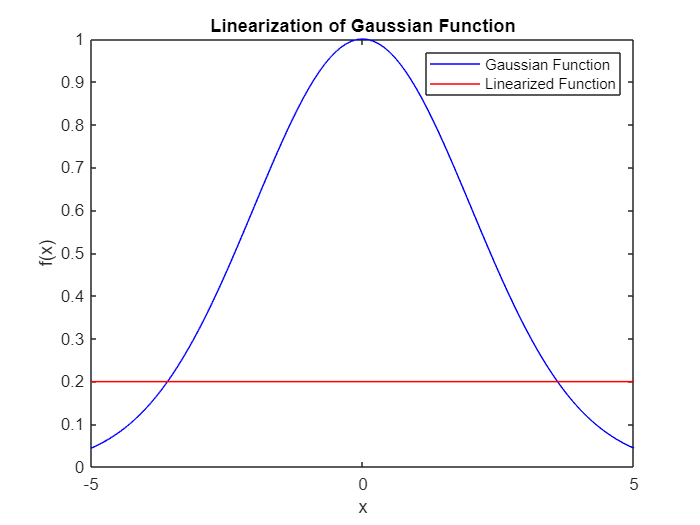

% Parameters
mean = 0;
sigma = 2;

% Range of x values
x = -5:0.1:5;

% Gaussian function
gaussian = exp(-(x-mean).^2/(2*sigma^2));

% Linearization point
linearizationPoint = 0;

% Linearized function
linearized = (1/(sqrt(2*pi)*sigma)) * exp(-(linearizationPoint-mean)^2/(2*sigma^2)) ...
    * (1 - ((x-linearizationPoint)*(linearizationPoint-mean))/(sigma^2) ...
    + (((x-linearizationPoint).^2)*(linearizationPoint-mean)^2)/(2*sigma^4) ...
    - (((x-linearizationPoint).^3)*(linearizationPoint-mean)^3)/(6*sigma^6));

% Plotting
plot(x, gaussian, 'b', x, linearized, 'r');
legend('Gaussian Function', 'Linearized Function');
title('Linearization of Gaussian Function');
xlabel('x');
ylabel('f(x)');

A=[1 0.0001125 -0.05685 8.174e-006;
    0 1.01 0.01162 0.03003;
    0 -0.00384 0.9441 -0.0002962;
    0 0.6434 0.768 1.005];
B=[0.005288 0.03723 -0.1792 2.461]';
E_d=B;
D_f=[1;1;1];
C=[eye(3) zeros(3,1)];
D=zeros(3,1);
syms x x_dot u d y v
displayFormula('x_dot=A*x+B*u+Bd*d')

$$\dot{x}=\left(\begin{array}{cccc} 1 & \frac{9}{80000} & -\frac{1137}{20000} & \frac{1206269488468015}{147573952589676412928}\\ 0 & \frac{101}{100} & \frac{581}{50000} & \frac{3003}{100000}\\ 0 & -\frac{12}{3125} & \frac{9441}{10000} & -\frac{5463925594632769}{18446744073709551616}\\ 0 & \frac{3217}{5000} & \frac{96}{125} & \frac{201}{200} \end{array}\right)\,x+\left(\begin{array}{c} \frac{6096648916361007}{1152921504606846976}\\ \frac{3723}{100000}\\ -\frac{112}{625}\\ \frac{2461}{1000} \end{array}\right)\,u+\mathrm{Bd}\,d$$

displayFormula('y=C*x+Df*v')

$$y=\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0 \end{array}\right)\,x+\mathrm{Df}\,v$$

## Parity

Gd=ss(A,B,C,D)

Gd =
 
  A = 
               x1          x2          x3          x4
   x1           1   0.0001125    -0.05685   8.174e-06
   x2           0        1.01     0.01162     0.03003
   x3           0    -0.00384      0.9441  -0.0002962
   x4           0      0.6434       0.768       1.005
 
  B = 
             u1
   x1  0.005288
   x2   0.03723
   x3   -0.1792
   x4     2.461
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.



Ho=obsv(A,C)

Ho =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0
    1.0000    0.0001   -0.0568    0.0000
         0    1.0100    0.0116    0.0300
         0   -0.0038    0.9441   -0.0003
    1.0000    0.0004   -0.1105    0.0000
         0    1.0394    0.0458    0.0605
         0   -0.0077    0.8911   -0.0007
    1.0000    0.0010   -0.1612    0.0001


rank(Ho)

ans = 4

rank(C)

ans = 3

a=rank(Ho)/rank(C);
b=rank(Ho)+rank(C)-1;
disp(['s must be in  [',num2str(a),',',num2str(b),']'])

s must be in  [1.3333,6]


s=2;
Hos = [C ; C*A ; C*A*A]

Hos =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0
    1.0000    0.0001   -0.0568    0.0000
         0    1.0100    0.0116    0.0300
         0   -0.0038    0.9441   -0.0003
    1.0000    0.0004   -0.1105    0.0000
         0    1.0394    0.0458    0.0605
         0   -0.0077    0.8911   -0.0007


Hus = [D zeros(3,2) ; C*B D zeros(3,1) ; C*A*B C*B D]

Hus =          0         0         0
         0         0         0
         0         0         0
    0.0053         0         0
    0.0372         0         0
   -0.1792         0         0
    0.0155    0.0053         0
    0.1094    0.0372         0
   -0.1701   -0.1792         0


Hfs = [D_f zeros(3,2) ; zeros(3,1) D_f zeros(3,1) ; zeros(3,2) D_f]

Hfs =      1     0     0
     1     0     0
     1     0     0
     0     1     0
     0     1     0
     0     1     0
     0     0     1
     0     0     1
     0     0     1


Hds = [zeros(3,3) ; C*E_d zeros(3,2) ; C*A*E_d C*E_d zeros(3,1)]

Hds =          0         0         0
         0         0         0
         0         0         0
    0.0053         0         0
    0.0372         0         0
   -0.1792         0         0
    0.0155    0.0053         0
    0.1094    0.0372         0
   -0.1701   -0.1792         0


[a,b,c]=svd(Hos);
NB=a(:,length(a))';
[v,landa]=eig(NB*(Hds*Hds')*NB',NB*(Hfs*Hfs')*NB');
V_s=v*NB

V_s =    -0.0206   -0.0042   -0.5308    0.0131    0.0023   -0.1899    0.0076    0.0071    0.7983


## Factorization

Gf=tf(minreal(ss(A,zeros(4,1),C,D_f)))

4 states removed.

Gf =
 
  From input to output...
   1:  1
 
   2:  1
 
   3:  1
 
Static gain.



Gu=tf(minreal(ss(A,B,C,D)))

Gu =
 
  From input to output...
       0.005288 s^3 - 0.005436 s^2 - 0.005192 s + 0.005154
   1:  ---------------------------------------------------
         s^4 - 3.959 s^3 + 5.857 s^2 - 3.839 s + 0.9403
 
       0.03723 s^2 - 0.0007435 s - 0.03649
   2:  -----------------------------------
       s^3 - 2.959 s^2 + 2.898 s - 0.9403
 
        -0.1792 s^2 + 0.3602 s - 0.1778
   3:  ----------------------------------
       s^3 - 2.959 s^2 + 2.898 s - 0.9403
 
Continuous-time transfer function.



G_d=tf(minreal(ss(A,E_d,C,D)))

G_d =
 
  From input to output...
       0.005288 s^3 - 0.005436 s^2 - 0.005192 s + 0.005154
   1:  ---------------------------------------------------
         s^4 - 3.959 s^3 + 5.857 s^2 - 3.839 s + 0.9403
 
       0.03723 s^2 - 0.0007435 s - 0.03649
   2:  -----------------------------------
       s^3 - 2.959 s^2 + 2.898 s - 0.9403
 
        -0.1792 s^2 + 0.3602 s - 0.1778
   3:  ----------------------------------
       s^3 - 2.959 s^2 + 2.898 s - 0.9403
 
Continuous-time transfer function.



L=transpose(place(A',C',[-20 -21 -22 -23]))

L = 	1.0e+04 *

    0.0022   -0.0000    0.0000
   -0.0004    0.0045   -0.0001
    0.0000   -0.0000    0.0023
   -0.2673    1.6801   -0.0638


M=tf(minreal(ss(A-L*C,L,-C,eye(3))))  

M =
 
  From input 1 to output...
       s^4 + 63.79 s^3 + 1332 s^2 + 8630 s - 1.003e04
   1:  -----------------------------------------------
       s^4 + 86 s^3 + 2771 s^2 + 3.965e04 s + 2.125e05
 
            3.519 s^3 + 149.5 s^2 + 1510 s - 1663
   2:  -----------------------------------------------
       s^4 + 86 s^3 + 2771 s^2 + 3.965e04 s + 2.125e05
 
          -0.4565 s^3 - 19.18 s^2 - 190.6 s + 210.3
   3:  -----------------------------------------------
       s^4 + 86 s^3 + 2771 s^2 + 3.965e04 s + 2.125e05
 
  From input 2 to output...
         0.0114 s^3 - 0.01459 s^2 - 5.511 s + 3.434
   1:  -----------------------------------------------
       s^4 + 86 s^3 + 2771 s^2 + 3.965e04 s + 2.125e05
 
        s^4 + 40.98 s^3 + 376.3 s^2 - 884.6 s + 457.8
   2:  -----------------------------------------------
       s^4 + 86 s^3 + 2771 s^2 + 3.965e04 s + 2.125e05
 
           0.2277 s^3 + 9.513 s^2 + 96.5 s - 64.23
   3:  -----------------------------------------------
       s^4

N=tf(minreal(ss(A-L*C,B,C,zeros(3,1))))

N =
 
  From input to output...
         0.005288 s^3 + 0.4199 s^2 + 10.69 s + 88.17
   1:  -----------------------------------------------
       s^4 + 86 s^3 + 2771 s^2 + 3.965e04 s + 2.125e05
 
          0.03723 s^3 + 1.504 s^2 + 13.35 s - 37.99
   2:  -----------------------------------------------
       s^4 + 86 s^3 + 2771 s^2 + 3.965e04 s + 2.125e05
 
           -0.1792 s^3 - 11.5 s^2 - 245.7 s - 1747
   3:  -----------------------------------------------
       s^4 + 86 s^3 + 2771 s^2 + 3.965e04 s + 2.125e05
 
Continuous-time transfer function.



norm(M*G_d)

ans = Inf

norm(M*Gf)

ans = Inf

R=[1 0 0];
X=M*G_d

X =
 
  From input to output...
                                                                                                                     
         0.005288 s^21 + 1.277 s^20 + 138.4 s^19 + 8862 s^18 + 3.706e05 s^17 + 1.054e07 s^16 + 2.047e08 s^15         
                                                                                                                     
                 + 2.626e09 s^14 + 1.986e10 s^13 + 5.281e10 s^12 - 3.407e11 s^11 - 1.958e12 s^10 + 6.706e12 s^9      
                                                                                                                     
                 + 2.253e13 s^8 - 1.607e14 s^7 + 4.075e14 s^6 - 5.993e14 s^5 + 5.669e14 s^4 - 3.523e14 s^3           
                                                                                                                     
                                                                                + 1.398e14 s^2 - 3.228e13 s + 3.31e12
                        

% g=spectralfact(X)

H_x=-R*N

H_x =
 
   -0.005288 s^3 - 0.4199 s^2 - 10.69 s - 88.17
  -----------------------------------------------
  s^4 + 86 s^3 + 2771 s^2 + 3.965e04 s + 2.125e05
 
Continuous-time transfer function.



H_y=R*M

H_y =
 
  From input 1 to output:
  s^4 + 63.79 s^3 + 1332 s^2 + 8630 s - 1.003e04
  -----------------------------------------------
  s^4 + 86 s^3 + 2771 s^2 + 3.965e04 s + 2.125e05
 
  From input 2 to output:
    0.0114 s^3 - 0.01459 s^2 - 5.511 s + 3.434
  -----------------------------------------------
  s^4 + 86 s^3 + 2771 s^2 + 3.965e04 s + 2.125e05
 
  From input 3 to output:
      -0.3717 s^3 - 14.33 s^2 - 100.1 s + 756
  -----------------------------------------------
  s^4 + 86 s^3 + 2771 s^2 + 3.965e04 s + 2.125e05
 
Continuous-time transfer function.

